# 1

a)

probs_1a = ones(1,6)/6;
subplot(1,2,1);
stem(1:6,probs_1a);

b)

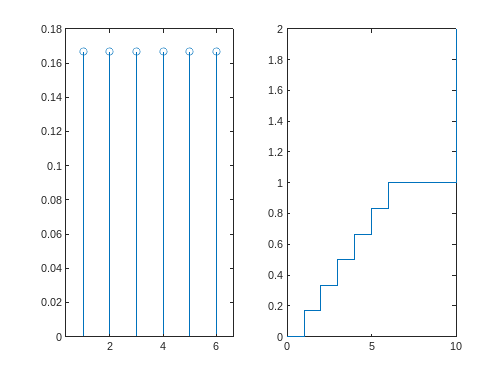

subplot(1,2,2);
xx_1b = [0 1:6 10];
probs_xx_1b = [0 probs_1a 1];
stairs(xx_1b,cumsum(probs_xx_1b));

# 2

a)

S = [nota1, nota2, nota3, nota4, nota5, ... , nota100]

Probabilidade de qualquer acontecimento elementar do espaço de amostragem S é 1/100.

b)

S = [5, 50, 100]

P(X = 5) = 0.9

P(X = 50) = 0.09

P(X = 100) = 0.01

x_2b = [5, 50, 100];
y_2b = [0.9,0.09,0.01];
stem(x_2b,y_2b)

c)

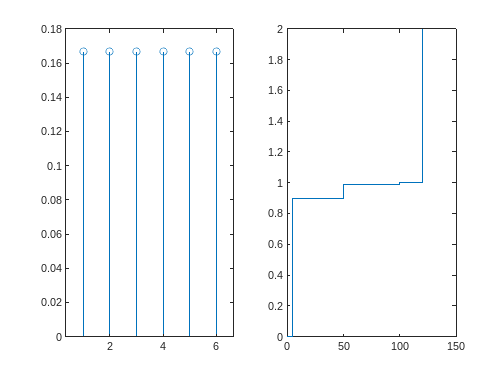

xx_2c = [0 x_2b 120];
yy_2c = [0 y_2b 1];
stairs(xx_2c,cumsum(yy_2c));

# 3

a)

N_experiencias_3 = 1e5;
n_lancamentos_3a = 4;
experiencias_3a = rand(n_lancamentos_3a,N_experiencias_3);
prob_coroa_3a = sum(experiencias_3a < 0.5)

prob_coroa_3a =      1     2     1     2     1     1     1     2     3     2     2     3     1     3     2     1     1     3     2     3     1     1     3     1     3     2     2     2     2     2     2     2     2     4     1     1     4     4     2     3     3     2     3     3     1     2     2     1     4     0


x_coroa_3a = 0:4;
y_coroa_3a = [];
[count,number]= groupcounts(prob_coroa_3a(:));
funcao_massa_de_probabilidade = count/N_experiencias_3

funcao_massa_de_probabilidade =     0.0619
    0.2503
    0.3741
    0.2513
    0.0623


b)

EX_3b = sum(funcao_massa_de_probabilidade .* x_coroa_3a(:)); %valor esperado
M_xx_3b = sum(funcao_massa_de_probabilidade.*(x_coroa_3a(:).^2)); %momento de segunda ordem
variancia_3b = M_xx_3b - (EX_3b^2);
desvio_padrao_3b = sqrt(M_xx_3b - (EX_3b^2));

c)

A distribuição é binomial.

P(X=k) = nchoosek(n,k)*p^k*(1-p)^(n-k)

d)

P(X=0) = 1/16

P(X=1) = 4/16

P(X=2) = 6/16

P(X=3) = 4/16

P(X=4) = 1/16

e)

E[X] = 1/16 * 0 + 4/16 * 1 + 6/16 * 2 + 4/16 * 3 + 1/16 * 4 = 2

Var(X) = (1/16 * 0 + 4/16 * 1 + 6/16 * 4 + 4/16 * 9 + 1/16 * 16) - 3.76 = 1

f)

i) 4/16 + 6/16 + 1/16 = 11/16

ii) 1/16 + 4/16 = 5/16

iii) 4/16 + 6/16 + 4/16 = 14/16

# 4

a)

N_experiencias_4 = 1e5;
n_amostras = 5;
experiencias_4a = rand(n_amostras,N_experiencias_4) < 0.5;
resultados_4a = sum(experiencias_4a);

i)

funcao_massa_probabilidade_4a = groupcounts(resultados_4a(:))./N_experiencias_4;

ii)

x_4a = 0:8;
y_4a = [0 funcao_massa_probabilidade_4a.' 0 0];
stairs(x_4a,cumsum(y_4a));

iii)

prob_4a = sum(funcao_massa_probabilidade_4a([1,2,3],:));

b)

P(X=0)= 1/32

P(X=1)= 5/32

P(X=2)= 10/32

P(X=3)= 10/32

P(X=4)= 5/32

P(X=5)= 1/3275

i) P(X < 0) = 0; P(0 <= X <= 1) = 6/32; P(0 <= X <= 2) = 16/32;P(0 <= X <= 3) = 26/32;P(0 <= X <= 4) = 31/32;P(0 <= X <= 5) = 32/32;P(X > 5) = 0;  

ii) 1/32 + 5/32 + 10/32 = 16/32 = 1/2

# 5

Para um avião com 2 motores se despenhar é preciso que 2 motores avariem,logo

nchoosek(n,k)*p^k*(1-p)^(n-k)

onde n = 2, k=2

1*p^2*(1-p)^0 = 1*p^2*(1) = p^2

Para um avião com 4 motores se depenhar temos 2 casos ou 3 motores avariados ou 4 motores avariados,logo

nchoosek(n,k)*p^k*(1-p)^(n-k)

onde n = 4, k=3

4*p^3*(1-p)^1

4*p^3*(1-p)

ou 

n=4, k=4

p^4

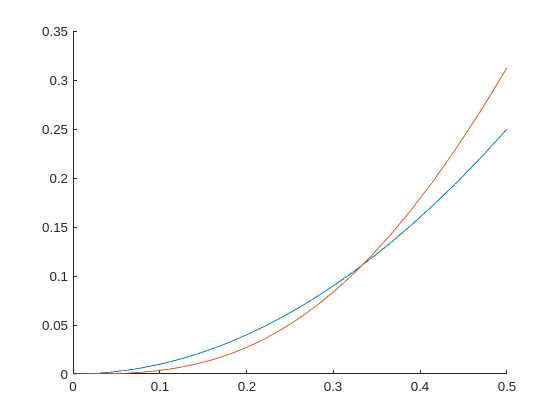

p= logspace(-3,log10(1/2),100);
y_1 = p.*p;
y_2 = (p.^4);
y_2 = y_2 + 4.*(p.^3).*(1.-p);
figure;
hold on
plot(p,y_1);
plot(p,y_2);
hold off

# 6

a)

n = 8000;
k = 7;
p = 10^(-3);
prob_6a = nchoosek(n,k)*p^k*(1-p)^(n-k)

prob_6a = 0.1396

b)

lambda_6b = n*p;
prob_6b = ((lambda_6b^k)/factorial(k))*exp(-lambda_6b);

# 7

a)

lambda_7a = 60;
prob_7a = ((lambda_7a^0)/factorial(0))*exp(-lambda_7a);

b)

probs_7b = [];
for i = 1:40
    probs_7b = [probs_7b , ((lambda_7a^i)/factorial(i))*exp(-lambda_7a)];
end
result_7b = 1 - sum(probs_7b);

# 8

lambda_8 = 0.02 * 100;
prob_8 = ((lambda_8^1)/factorial(1))*exp(-lambda_8) + ((lambda_8^0)/factorial(0))*exp(-lambda_8);

# 9

desvio_padrao_9 = 2;
valor_experado_9 = 14;
N_experiencias_9 = 1e5;

a)

experiencias_9_a = desvio_padrao_9*randn(1,N_experiencias_9) + valor_experado_9;
results_9a= experiencias_9_a(((experiencias_9_a <= 16) & (experiencias_9_a >= 12)));
answer_9a = size(results_9a,2)/N_experiencias_9;
normcdf([12,16],valor_experado_9,desvio_padrao_9);
answer_9a_analitica = 0.8413 - 0.1587;

b)

experiencias_9_b = desvio_padrao_9*randn(1,N_experiencias_9) + valor_experado_9;
results_9b= experiencias_9_a(((experiencias_9_b <= 18) & (experiencias_9_b >= 10)));
answer_9b = size(results_9b,2)/N_experiencias_9;
normcdf([10,18],valor_experado_9,desvio_padrao_9);
answer_9b_analitica = 0.9772 - 0.0228;

c)

experiencias_9_c = desvio_padrao_9*randn(1,N_experiencias_9) + valor_experado_9;
results_9c= experiencias_9_c(experiencias_9_c >= 10);
answer_9c = size(results_9c,2)/N_experiencias_9;
normcdf([10,20],valor_experado_9,desvio_padrao_9);
answer_9c_analitica = 0.9987 - 0.0228;

# Exercícios Suplementares

1

a)

N_experiencias_s1a = 1e5;
n_brinquedos_s1a = 8;
experiencias_s1a = rand(n_brinquedos_s1a,N_experiencias_s1a) < 0.017;
resultados_s1a = sum(experiencias_s1a) >= 1;
prob_s1a = sum(resultados_s1a)/N_experiencias_s1a;

prob_s1a = 0.1279

b)

experiencias_s1b = rand(n_brinquedos_s1a,N_experiencias_s1a) < 0.007;
resultados_s1b = sum(sum(experiencias_s1b));
media_s1b = resultados_s1b/(n_brinquedos_s1a*N_experiencias_s1a);

2

a)

experiencias_s2a = rand(n_brinquedos_s1a,N_experiencias_s1a) >= 0.017;
resultados_s2a = sum(experiencias_s2a) == 8;
prob_s2a = sum(resultados_s2a)/N_experiencias_s1a;

b)

prob_s2b = (nchoosek(8,8)*0.983^8)*((1-0.983)^(8-8));

c)

x_s2c = 2:20;
y_s2c = []


y_s2c =

     []



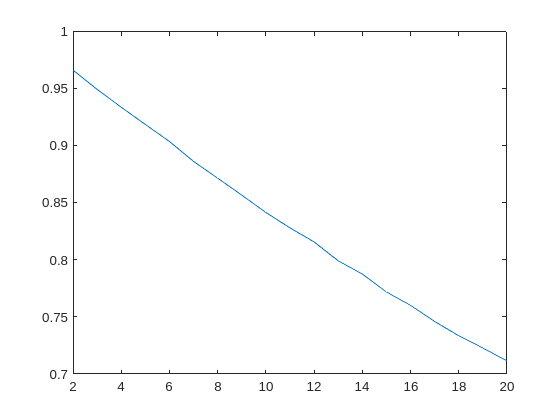

for i = x_s2c
    experiencias_s2c = rand(i,N_experiencias_s1a) >= 0.017;
    resultados_s2c = sum(experiencias_s2c) == i;
    prob_s2c = sum(resultados_s2c)/N_experiencias_s1a;
    y_s2c = [y_s2c prob_s2c ];
end
plot(x_s2c,y_s2c);

d)

Observando o gráfico anterior a capacidade máxima da caixa para garantir que a probabilidade de cada caixa não ter brinquedos com defeito seja

de pelo menos 0,9 é 6 brinquedos por caixa.

# 3

a)

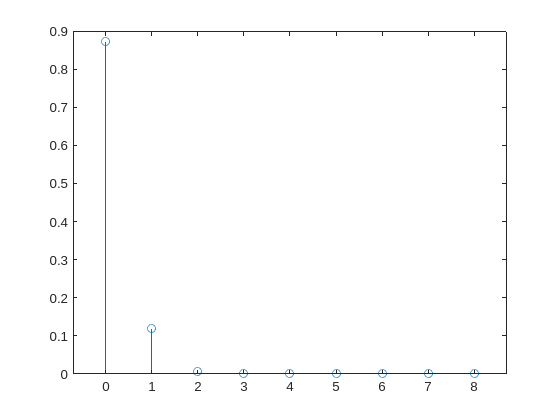

x_s3a = 0:8;
y_s3a = [];
for i = x_s3a
    experiencias_s3a = rand(8,N_experiencias_s1a) < 0.017;
    resultados_s3a = sum(experiencias_s3a) == i;
    prob_s3a = sum(resultados_s3a)/N_experiencias_s1a;
    y_s3a = [y_s3a prob_s3a ];
end
stem(x_s3a,y_s3a);

b)

prob_s3b = sum(y_s3a(:,2:8));

c)

valor_esperado_s3c = sum(y_s3a .* x_s3a);
variancia_s3c = sum(y_s3a .* (x_s3a.^2)) - (valor_esperado_s3c.^2);
desvio_padrao_s3c = variancia_s3c.^2;

d)

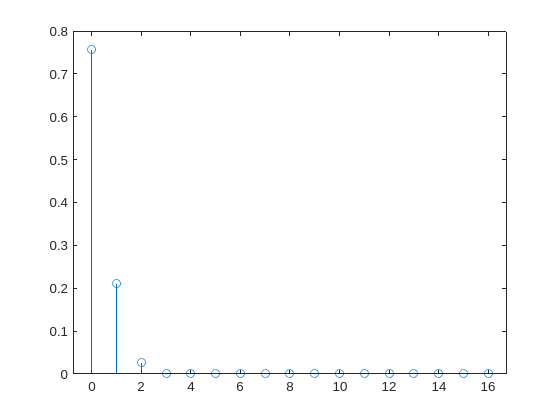

x_s3d = 0:16;
y_s3d = [];
for i = x_s3d
    experiencias_s3d = rand(16,N_experiencias_s1a) < 0.017;
    resultados_s3d = sum(experiencias_s3d) == i;
    prob_s3d = sum(resultados_s3d)/N_experiencias_s1a;
    y_s3d = [y_s3d prob_s3d];
end
stem(x_s3d,y_s3d);

prob_s3d = sum(y_s3d(:,2:16));
valor_esperado_s3d = sum(y_s3d .* x_s3d);
variancia_s3d = sum(y_s3d .* (x_s3d.^2)) - (valor_esperado_s3d.^2);
desvio_padrao_s3d = variancia_s3d.^2;

# 4

a)

n_brinquedos_s4a = 20;
comercialized_boxes = 0;
experiencias_s4a = rand(n_brinquedos_s4a,N_experiencias_s1a) < 0.008;
for i = 1:N_experiencias_s1a
    selected_toy = experiencias_s4a(randperm(20,1),i);
    if selected_toy == 0
        comercialized_boxes = comercialized_boxes + 1;
    end
end
prob_s4a = comercialized_boxes/N_experiencias_s1a;

b)

Para atingir o objetivo desejado o valor minimo de m seria 13.